# Time-periodic solution for the NLS equation on a dumbbell graph

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

tag='dumbbell';
nX = 32;
Phi = quantumGraphFromTemplate(tag,'discretization','Chebyshev','nX',nX);

## Initial Condition

The first step for our time evolution is developing a good initial condition. We will use a solution to the stationary problem.

First, we must generate solutions to the stationary problem.

nToPlot=4;
nDoubles=1;
nTriples=0;
diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

Saved to directory data\dumbbell\031.
Run number is 31.



options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
eigNumber=1;
[bn1,bl1]=continueFromEig(tag,diagramNumber,eigNumber,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\031\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.



Lambda0=-4;
edges=[1 2];
signs=[1 1];
filenumber=saveHighFrequencyStandingWave(tag,diagramNumber,Lambda0,edges,signs);

File saved to data\dumbbell\031\savedFunction.001.
File number is 1. 



options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
[bn2,bl2]=continueFromSaved(tag,diagramNumber,filenumber,-1,options);

N threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\031\branch002.
No branching bifurcations found.


Now load the excited state to find the perturbative terms for the soliton.

u = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'PhiColumn.010'));
mVec = load(fullfile('data',tag,getLabel(diagramNumber),['branch',getLabel(bn2)],'LambdaVec'));
mu = mVec(10);

Find the perturbative terms and create intial conditions.

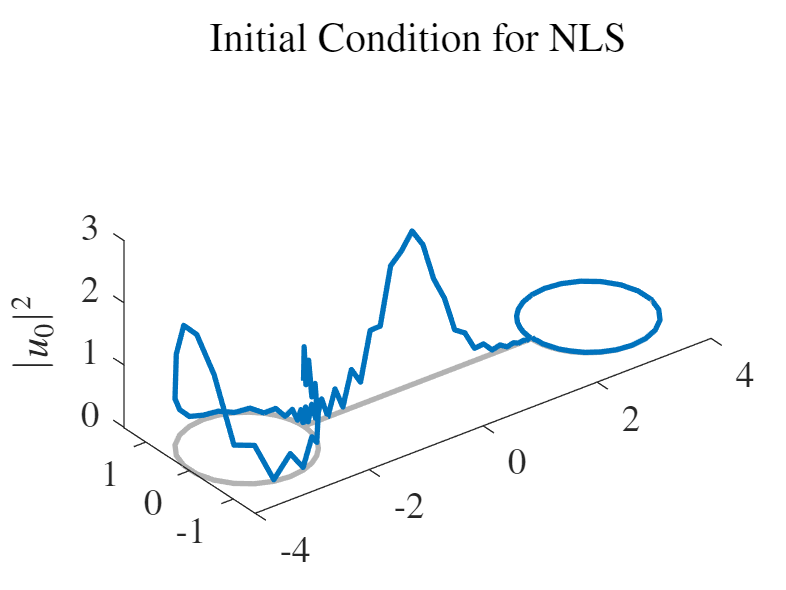

funcs = getGraphFcns(Phi);          % Defining our JL operator
JL = funcs.JL(u,mu);
[V,lambda] = eigsJL(Phi,JL,6);      % Finds eigenvalues for JL
f1 = V(1:102,2);
f2 = V(103:end,2);

u0 = u + f1 + conj(f2); %?????????????????????????????
Phi.plot(abs(u0).^2)
title('Initial Condition for NLS')
zlabel('$|u_0|^2$')
axis([-4 4 -1.5 1.5 -.01 3])
daspect([1 1 1])

## Period

This gives the initial guess for the period.

tend = lambda(2); %?????????????????????????????

## Time Periodic Solution

In addition to the initial condition, we need the step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used a modified version of the DoPri-8 scheme.

[t,u,period] = adjointContinuationMethod(Phi,u0,tend);

Operator '*' is not supported for operands of type 'function_handle'.

Error in adjointContinuationMethod>@(s,Q)DFstar(s,Q,Phi,f,u0,T)*Q (line 56)
    Qs = @(s,Q) DFstar(s,Q,Phi,f,u0,T)*Q;

Error in odearguments (line 90)
f0 = feval(ode,t0,y0,args{:});   % ODE15I sets args{

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every 1000th data point.

n = size(u,2);
scale = floor(n/1000);
for i=1:floor(n/scale)
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-4 4 -1.5 1.5 -.01 .2])
    daspect([1 1 .075])
    title(['$t=$',num2str(round(t(scale*i),2))])
    zlabel('$|u|^2$')
    drawnow
end

## Error analysis

Check for conservation of energy, mass and momentum.

energyDiff = zeros(floor(n/scale),1);
massDiff = zeros(floor(n/scale),1);
tplot = zeros(floor(n/scale),1);
D = Phi.derivative;

u0energy = Phi.dot( D*u(:,1) , conj(D*u(:,1)) ) - Phi.dot( u(:,1).^2 , conj(u(:,1)).^2 );
u0mass = Phi.dot(u(:,1),conj(u(:,1)));

for i=1:floor(n/scale)
    ui = u(:,scale*i);
    uiprime=D*ui;
    term1 = Phi.dot(uiprime,conj(uiprime));
    term2 = Phi.dot(ui.^2,conj(ui).^2);
    E = term1 - term2;
    
    energyDiff(i) = abs((E-u0energy)/u0energy);
    massDiff(i) = abs( (Phi.dot(ui,conj(ui)) - u0mass) / u0mass );
    tplot(i) = t(scale*i);
end


disp('')
figure
plot(tplot,energyDiff)
title('Energy error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')

figure
plot(tplot,massDiff)
title('Mass error relative to $u_0$')
xlabel('Time')
ylabel('Relative error')